
clear;


clockTimeLimit = 100; % 体験時間 (s)
period = 3; % 歩行周期 (s)

legForwardTimeRate = 3; % 足スライダ前進 時間比
legBackwardTimeRate = 4; % 足スライダ後退 時間比

stockForwardTimeRate = 3; % ストックスライダ前進 時間比
stockBackwardTimeRate = 4; % ストックスライダ後退 時間比

upTimeRate = 1; % 伸縮 持ち上げ 時間比
downTimeRate = 1; % 伸縮 降下 時間比

stockFlyingTimeRate = 3; % ストック空中時間比
stockGroundTimeRate = 4; % ストック接地時間比

tiltBackwardTimeRate = stockForwardTimeRate;
tiltForwardTimeRate = stockBackwardTimeRate;

liftLength = 50; % 椅子 リフト長 単位 (mm)
pedalLength = 60; % ペダル長 単位 (mm)
seatSlideForwardLength = 50; % 椅子 スライド長 単位 (mm)
seatSlideBackwardLength = 100; % 椅子 スライド長 単位 (mm)
extendLength = 150; % 伸縮長 単位 (mm)
stockSlideForwardLength = 100; % ストック スライド前方向長 単位 (mm)
stockSlideBackwardLength = 400; % ストック スライド後方向長 単位 (mm)
tiltBackwardDeg = 0; % ストック 後傾角度 (deg)
tiltForwardDeg = -20; % ストック 前傾角度 (deg)

stockStartTime = period/2 + period*legForwardTimeRate/(legForwardTimeRate * legBackwardTimeRate)*1/4;

椅子 リフト

L = liftLength; % スライド長 単位 (mm)
startClockTime = period/2; % 開始時刻 (s)
clockTimeU = 0; % 単位 (s)
clockTimeD = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 単位 (s)
deltaTimeU = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 単位 (s)
deltaTimeD = period*legBackwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 単位 (s)
positionU = L; % 単位 (mm)
positionD = 0; % 単位 (mm)

clockTimeUList = (startClockTime + clockTimeU):period:clockTimeLimit; % 単位 (s)
clockTimeDList = (startClockTime + clockTimeD):period:clockTimeLimit; % 単位 (s)
clockTimeUList = clockTimeUList(1:min([length(clockTimeUList), length(clockTimeDList)]));
clockTimeDList = clockTimeDList(1:min([length(clockTimeUList), length(clockTimeDList)]));
tmp = [clockTimeUList; clockTimeDList];
clockTime = tmp(:);
deltaTimeUList = deltaTimeU + 0*clockTimeUList;
deltaTimeDList = deltaTimeD + 0*clockTimeDList;
tmp = [deltaTimeUList; deltaTimeDList];
deltaTime = tmp(:);
positionUList = positionU + 0*clockTimeUList;
positionDList = positionD + 0*clockTimeDList;
tmp = [positionUList; positionDList];
absolutePosition = tmp(:);

clockTime(end+1) = clockTimeLimit + period/2;
deltaTime(end+1) = period/2;
absolutePosition(end+1) = 0;

useStiffness = zeros(size(clockTime));

lifter = table(clockTime, deltaTime, absolutePosition, useStiffness)

lifter = 67×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

        1.5       1.2857             50                0      
     2.7857       1.7143              0                0      
        4.5       1.2857             50                0      
     5.7857       1.7143              0                0      
        7.5       1.2857             50                0      
     8.7857       1.7143              0                0      
       10.5       1.2857             50                0      
     11.786       1.7143              0                0      
       13.5       1.2857             50                0      
     14.786       1.7143              0                0      
       16.5       1.2857             50                0      
     17.786       1.7143              0                0      
       19.5       1.2857             50                0      
     20.786       1.7143          

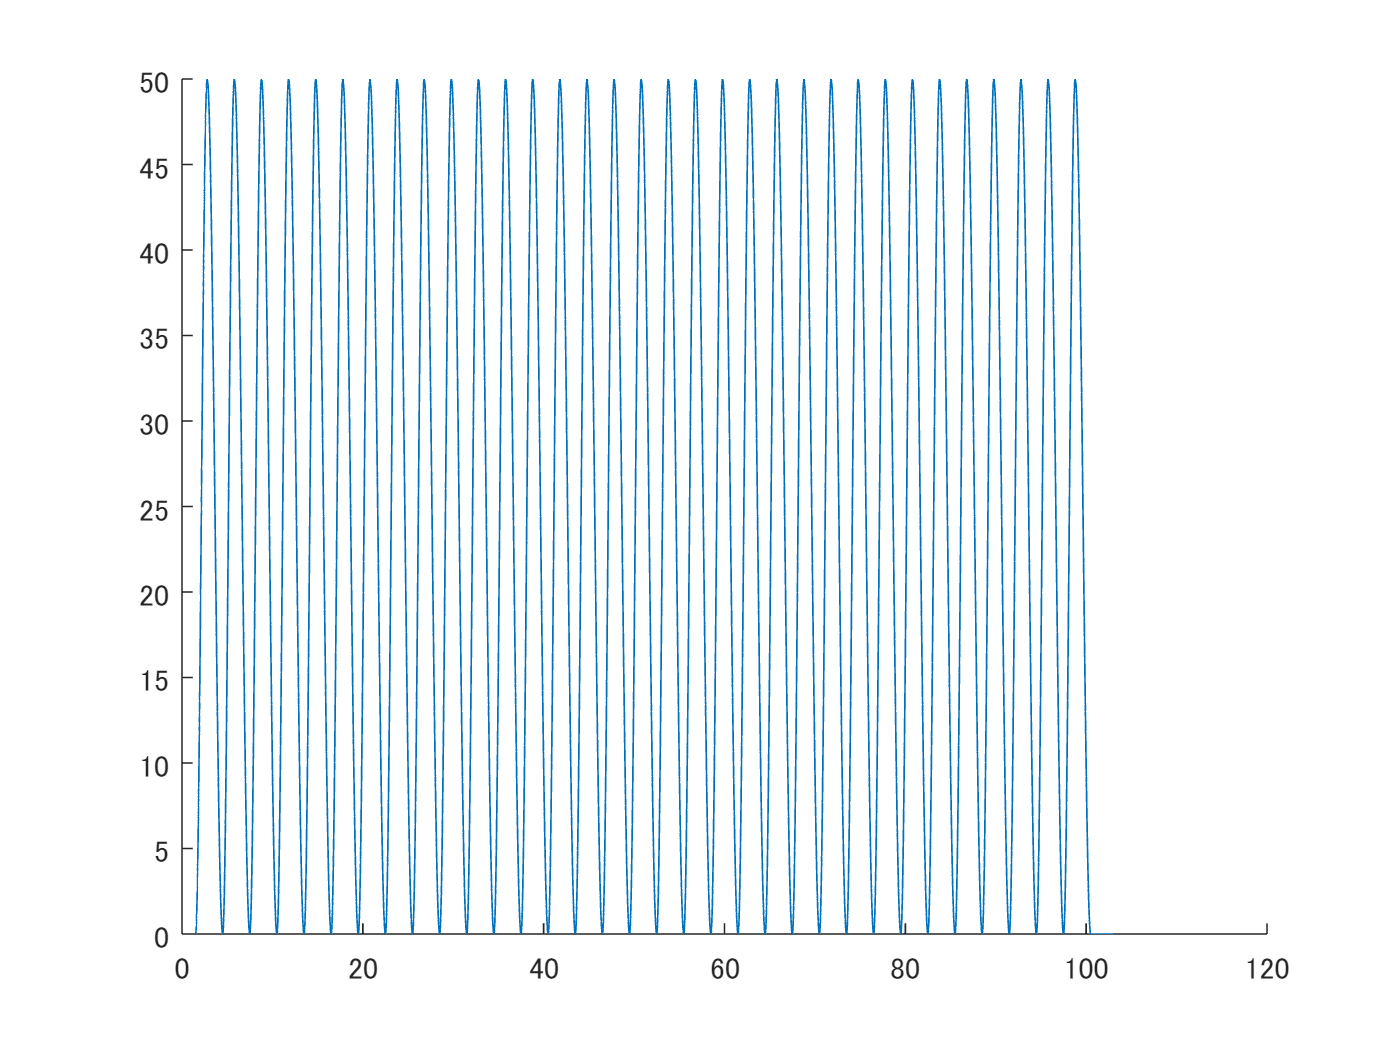

writetable(lifter, "lifter.csv");
figure;
[lifter_x, lifter_t] = showGraph(clockTime, deltaTime, absolutePosition);

左ペダル

L = pedalLength; % スライド長 単位 (mm)
startClockTime = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 開始時刻 (s)
clockTimeU = period*legBackwardTimeRate/(legForwardTimeRate + legBackwardTimeRate)/2; % 単位 (s)
clockTimeD = period*legBackwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 単位 (s)
deltaTimeU = period*legBackwardTimeRate/(legForwardTimeRate + legBackwardTimeRate)/2; % 単位 (s)
deltaTimeD = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate)*3/4; % 単位 (s)
positionU = L; % 単位 (mm)
positionD = 0; % 単位 (mm)

clockTimeUList = (startClockTime + clockTimeU):period:clockTimeLimit; % 単位 (s)
clockTimeDList = (startClockTime + clockTimeD):period:clockTimeLimit; % 単位 (s)
clockTimeUList = clockTimeUList(1:min([length(clockTimeUList), length(clockTimeDList)]));
clockTimeDList = clockTimeDList(1:min([length(clockTimeUList), length(clockTimeDList)]));
tmp = [clockTimeUList; clockTimeDList];
clockTime = tmp(:);
deltaTimeUList = deltaTimeU + 0*clockTimeUList;
deltaTimeDList = deltaTimeD + 0*clockTimeDList;
tmp = [deltaTimeUList; deltaTimeDList];
deltaTime = tmp(:);
positionUList = positionU + 0*clockTimeUList;
positionDList = positionD + 0*clockTimeDList;
tmp = [positionUList; positionDList];
absolutePosition = tmp(:);

clockTime(end+1) = clockTimeLimit + period/2;
deltaTime(end+1) = period/2;
absolutePosition(end+1) = 0;

useStiffness = zeros(size(clockTime));

leftPedal = table(clockTime, deltaTime, absolutePosition, useStiffness)

leftPedal = 67×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

     2.1429       0.85714            60                0      
          3       0.96429             0                0      
     5.1429       0.85714            60                0      
          6       0.96429             0                0      
     8.1429       0.85714            60                0      
          9       0.96429             0                0      
     11.143       0.85714            60                0      
         12       0.96429             0                0      
     14.143       0.85714            60                0      
         15       0.96429             0                0      
     17.143       0.85714            60                0      
         18       0.96429             0                0      
     20.143       0.85714            60                0      
         21       0.96429      

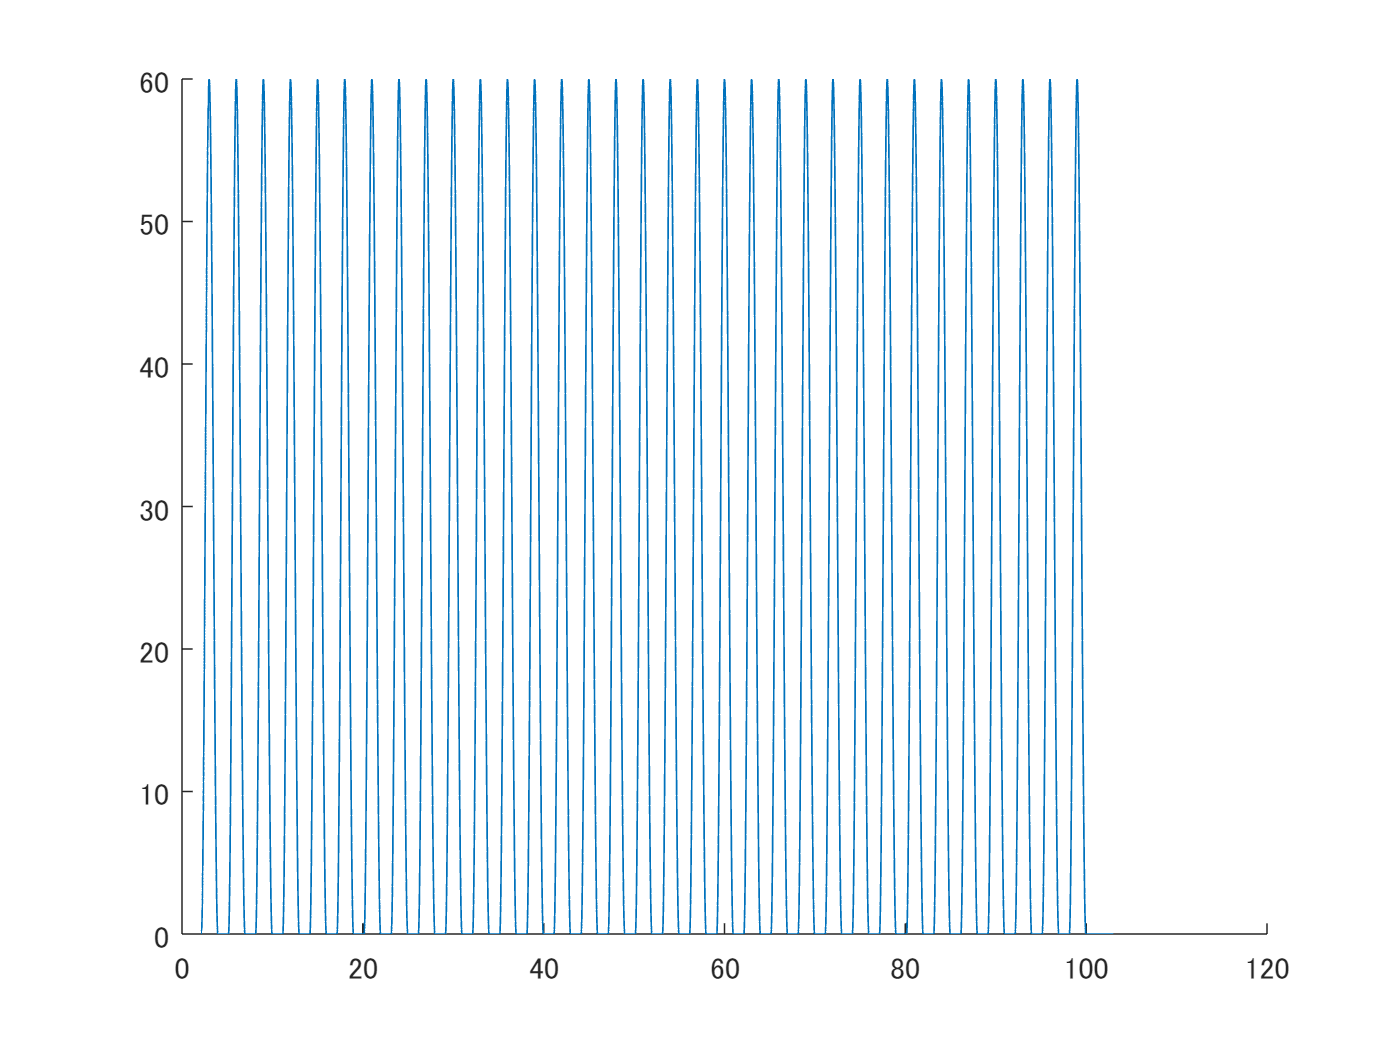

writetable(leftPedal, "leftPedal.csv");
figure;
[leftPedal_x, leftPedal_t] = showGraph(clockTime, deltaTime, absolutePosition);

右ペダル

L = pedalLength; % スライド長 単位 (mm)
startClockTime = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 開始時刻 (s)
clockTimeU = period*legBackwardTimeRate/(legForwardTimeRate + legBackwardTimeRate)/2; % 単位 (s)
clockTimeD = period*legBackwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 単位 (s)
deltaTimeU = period*legBackwardTimeRate/(legForwardTimeRate + legBackwardTimeRate)/2; % 単位 (s)
deltaTimeD = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate)*3/4; % 単位 (s)
positionU = L; % 単位 (mm)
positionD = 0; % 単位 (mm)

clockTimeUList = (startClockTime + clockTimeU):period:clockTimeLimit; % 単位 (s)
clockTimeDList = (startClockTime + clockTimeD):period:clockTimeLimit; % 単位 (s)
clockTimeUList = clockTimeUList(1:min([length(clockTimeUList), length(clockTimeDList)]));
clockTimeDList = clockTimeDList(1:min([length(clockTimeUList), length(clockTimeDList)]));
tmp = [clockTimeUList; clockTimeDList];
clockTime = tmp(:);
deltaTimeUList = deltaTimeU + 0*clockTimeUList;
deltaTimeDList = deltaTimeD + 0*clockTimeDList;
tmp = [deltaTimeUList; deltaTimeDList];
deltaTime = tmp(:);
positionUList = positionU + 0*clockTimeUList;
positionDList = positionD + 0*clockTimeDList;
tmp = [positionUList; positionDList];
absolutePosition = tmp(:);

clockTime(end+1) = clockTimeLimit + period/2;
deltaTime(end+1) = period/2;
absolutePosition(end+1) = 0;

useStiffness = zeros(size(clockTime));

rightPedal = table(clockTime, deltaTime, absolutePosition, useStiffness)

rightPedal = 67×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

     2.1429       0.85714            60                0      
          3       0.96429             0                0      
     5.1429       0.85714            60                0      
          6       0.96429             0                0      
     8.1429       0.85714            60                0      
          9       0.96429             0                0      
     11.143       0.85714            60                0      
         12       0.96429             0                0      
     14.143       0.85714            60                0      
         15       0.96429             0                0      
     17.143       0.85714            60                0      
         18       0.96429             0                0      
     20.143       0.85714            60                0      
         21       0.96429     

writetable(rightPedal, "rightPedal.csv");
figure;
[rightPedal_x, rightPedal_t] = showGraph(clockTime, deltaTime, absolutePosition);

椅子　左　スライダ

startClockTime = 0; % 開始時刻 (s)
clockTimeF = 0; % 単位 (s)
clockTimeB = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 単位 (s)
clockTimeBB = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate) + period*legBackwardTimeRate/(legForwardTimeRate + legBackwardTimeRate)/2; % 単位 (s)
clockTimeB = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 単位 (s)
deltaTimeF = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 単位 (s)
deltaTimeB = period*legBackwardTimeRate/(legForwardTimeRate + legBackwardTimeRate)/2; % 単位 (s)
deltaTimeBB = period*legBackwardTimeRate/(legForwardTimeRate + legBackwardTimeRate)/2; % 単位 (s)
deltaTimeB = period*legBackwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 単位 (s)
positionF = seatSlideForwardLength; % 単位 (mm)
positionB = 0.5*seatSlideForwardLength - 0.5*seatSlideBackwardLength; % 単位 (mm)
positionBB = -seatSlideBackwardLength; % 単位 (mm)

clockTimeFList = (startClockTime + clockTimeF):period:clockTimeLimit; % 単位 (s)
clockTimeBList = (startClockTime + clockTimeB):period:clockTimeLimit; % 単位 (s)
clockTimeBBList = (startClockTime + clockTimeBB):period:clockTimeLimit; % 単位 (s)
clockTimeFList = clockTimeFList(1:min([length(clockTimeFList), length(clockTimeBList), length(clockTimeBBList)]));
clockTimeBList = clockTimeBList(1:min([length(clockTimeFList), length(clockTimeBList), length(clockTimeBBList)]));
clockTimeBBList = clockTimeBBList(1:min([length(clockTimeFList), length(clockTimeBList), length(clockTimeBBList)]));
% tmp = [clockTimeFList; clockTimeBList; clockTimeBBList];
tmp = [clockTimeFList; clockTimeBList];
clockTime = tmp(:);
deltaTimeFList = deltaTimeF + 0*clockTimeFList;
deltaTimeBList = deltaTimeB + 0*clockTimeBList;
deltaTimeBBList = deltaTimeBB + 0*clockTimeBBList;
% tmp = [deltaTimeFList; deltaTimeBList; deltaTimeBBList];
tmp = [deltaTimeFList; deltaTimeBList];
deltaTime = tmp(:);
positionFList = positionF + 0*clockTimeFList;
positionBList = positionB + 0*clockTimeBList;
positionBBList = positionBB + 0*clockTimeBBList;
% tmp = [positionFList; positionBList; positionBBList];
tmp = [positionFList; positionBBList];
absolutePosition = tmp(:);

clockTime(end+1) = clockTimeLimit + period/2;
deltaTime(end+1) = period/2;
absolutePosition(end+1) = 0;

useStiffness = zeros(size(clockTime));

seatLeftSlider = table(clockTime, deltaTime, absolutePosition, useStiffness)

seatLeftSlider = 67×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

          0       1.2857              50               0      
     1.2857       1.7143            -100               0      
          3       1.2857              50               0      
     4.2857       1.7143            -100               0      
          6       1.2857              50               0      
     7.2857       1.7143            -100               0      
          9       1.2857              50               0      
     10.286       1.7143            -100               0      
         12       1.2857              50               0      
     13.286       1.7143            -100               0      
         15       1.2857              50               0      
     16.286       1.7143            -100               0      
         18       1.2857              50               0      
     19.286       1.7143  

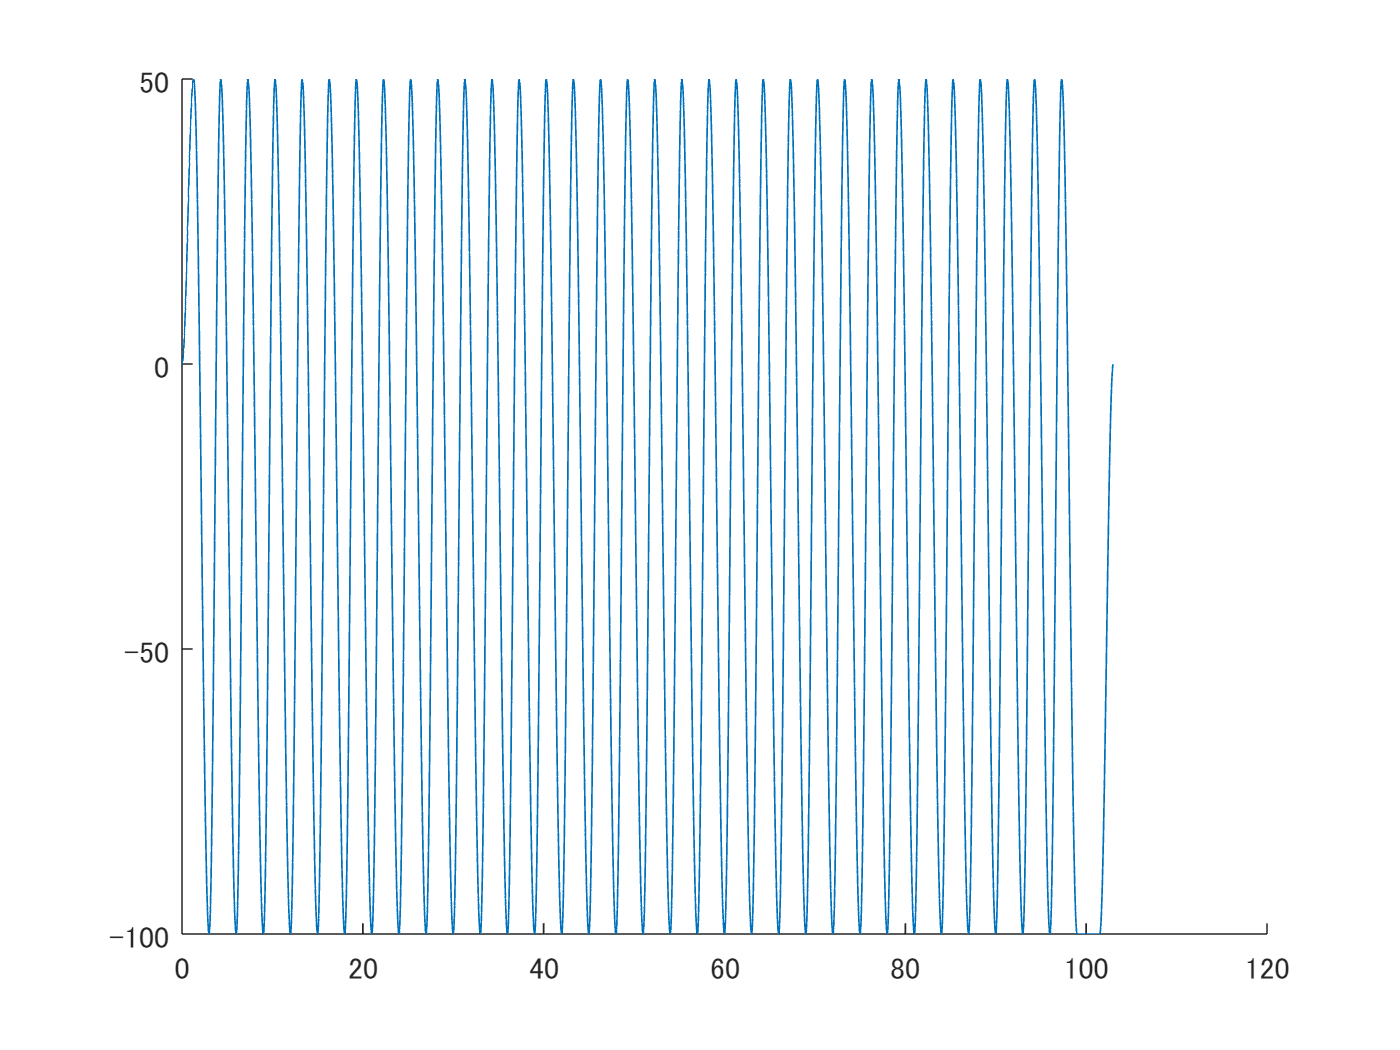

writetable(seatLeftSlider, "seatLeftSlider.csv");
figure;
[seatLeftSlider_x, seatLeftSlider_t] = showGraph(clockTime, deltaTime, absolutePosition);

椅子　右　スライダ

startClockTime = 0; % 開始時刻 (s)
clockTimeF = 0; % 単位 (s)
clockTimeB = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 単位 (s)
clockTimeBB = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate) + period*legBackwardTimeRate/(legForwardTimeRate + legBackwardTimeRate)/2; % 単位 (s)
clockTimeB = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 単位 (s)
deltaTimeF = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 単位 (s)
deltaTimeB = period*legBackwardTimeRate/(legForwardTimeRate + legBackwardTimeRate)/2; % 単位 (s)
deltaTimeBB = period*legBackwardTimeRate/(legForwardTimeRate + legBackwardTimeRate)/2; % 単位 (s)
deltaTimeB = period*legBackwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 単位 (s)
positionF = seatSlideForwardLength; % 単位 (mm)
positionB = 0.5*seatSlideForwardLength - 0.5*seatSlideBackwardLength; % 単位 (mm)
positionBB = -seatSlideBackwardLength; % 単位 (mm)

clockTimeFList = (startClockTime + clockTimeF):period:clockTimeLimit; % 単位 (s)
clockTimeBList = (startClockTime + clockTimeB):period:clockTimeLimit; % 単位 (s)
clockTimeBBList = (startClockTime + clockTimeBB):period:clockTimeLimit; % 単位 (s)
clockTimeFList = clockTimeFList(1:min([length(clockTimeFList), length(clockTimeBList), length(clockTimeBBList)]));
clockTimeBList = clockTimeBList(1:min([length(clockTimeFList), length(clockTimeBList), length(clockTimeBBList)]));
clockTimeBBList = clockTimeBBList(1:min([length(clockTimeFList), length(clockTimeBList), length(clockTimeBBList)]));
% tmp = [clockTimeFList; clockTimeBList; clockTimeBBList];
tmp = [clockTimeFList; clockTimeBList];
clockTime = tmp(:);
deltaTimeFList = deltaTimeF + 0*clockTimeFList;
deltaTimeBList = deltaTimeB + 0*clockTimeBList;
deltaTimeBBList = deltaTimeBB + 0*clockTimeBBList;
% tmp = [deltaTimeFList; deltaTimeBList; deltaTimeBBList];
tmp = [deltaTimeFList; deltaTimeBList];
deltaTime = tmp(:);
positionFList = positionF + 0*clockTimeFList;
positionBList = positionB + 0*clockTimeBList;
positionBBList = positionBB + 0*clockTimeBBList;
% tmp = [positionFList; positionBList; positionBBList];
tmp = [positionFList; positionBBList];
absolutePosition = tmp(:);

clockTime(end+1) = clockTimeLimit + period/2;
deltaTime(end+1) = period/2;
absolutePosition(end+1) = 0;

useStiffness = zeros(size(clockTime));

seatRightSlider = table(clockTime, deltaTime, absolutePosition, useStiffness)

seatRightSlider = 67×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

          0       1.2857              50               0      
     1.2857       1.7143            -100               0      
          3       1.2857              50               0      
     4.2857       1.7143            -100               0      
          6       1.2857              50               0      
     7.2857       1.7143            -100               0      
          9       1.2857              50               0      
     10.286       1.7143            -100               0      
         12       1.2857              50               0      
     13.286       1.7143            -100               0      
         15       1.2857              50               0      
     16.286       1.7143            -100               0      
         18       1.2857              50               0      
     19.286       1.7143 

writetable(seatRightSlider, "seatRightSlider.csv");
% figure;
% showGraphEveryCmd(clockTime, deltaTime, absolutePosition)
figure;
[seatRightSlider_x, seatRightSlider_t] = showGraph(clockTime, deltaTime, absolutePosition);


L = extendLength; % スライド長 単位 (mm)
startClockTime = stockStartTime; % 開始時刻 (s)
clockTimeU = 0; % 単位 (s)
clockTimeD = period*stockFlyingTimeRate/(stockFlyingTimeRate + stockGroundTimeRate) * upTimeRate/(upTimeRate + downTimeRate); % 単位 (s)
clockTimeSlowD = period*stockFlyingTimeRate/(stockFlyingTimeRate + stockGroundTimeRate) + 0.1; % 単位 (s)
deltaTimeU = period*stockFlyingTimeRate/(stockFlyingTimeRate + stockGroundTimeRate) * upTimeRate/(upTimeRate + downTimeRate); % 単位 (s)
deltaTimeD = period*stockFlyingTimeRate/(stockFlyingTimeRate + stockGroundTimeRate) * downTimeRate/(upTimeRate + downTimeRate); % 単位 (s)
deltaTimeSlowD = period*stockGroundTimeRate/(stockFlyingTimeRate + stockGroundTimeRate) - 0.1; % 単位 (s)
positionU = L; % 単位 (mm)
positionD = L/2; % 単位 (mm)
positionSlowD = 0; % 単位 (mm)

clockTimeUList = (startClockTime + clockTimeU):period:clockTimeLimit; % 単位 (s)
clockTimeDList = (startClockTime + clockTimeD):period:clockTimeLimit; % 単位 (s)
clockTimeSlowDList = (startClockTime + clockTimeSlowD):period:clockTimeLimit; % 単位 (s)
clockTimeUList = clockTimeUList(1:min([length(clockTimeUList), length(clockTimeDList), length(clockTimeSlowDList)]));
clockTimeDList = clockTimeDList(1:min([length(clockTimeUList), length(clockTimeDList), length(clockTimeSlowDList)]));
clockTimeSlowDList = clockTimeSlowDList(1:min([length(clockTimeUList), length(clockTimeDList), length(clockTimeSlowDList)]));
tmp = [clockTimeUList; clockTimeDList; clockTimeSlowDList];
clockTime = tmp(:);
deltaTimeUList = deltaTimeU + 0*clockTimeUList;
deltaTimeDList = deltaTimeD + 0*clockTimeDList;
deltaTimeSlowDList = deltaTimeSlowD + 0*clockTimeSlowDList;
tmp = [deltaTimeUList; deltaTimeDList; deltaTimeSlowDList];
deltaTime = tmp(:);
positionUList = positionU + 0*clockTimeUList;
positionDList = positionD + 0*clockTimeDList;
positionSlowDList = positionSlowD + 0*clockTimeSlowDList;
tmp = [positionUList; positionDList; positionSlowDList];
absolutePosition = tmp(:);

tmp = [zeros(size(clockTimeUList)); ones(size(clockTimeDList)); zeros(size(clockTimeSlowDList));];
useStiffness = tmp(:);

clockTime(end+1) = clockTimeLimit + period/2;
deltaTime(end+1) = period/2;
absolutePosition(end+1) = 0;
useStiffness(end+1) = 0;

stockLeftExtend = table(clockTime, deltaTime, absolutePosition, useStiffness)

stockLeftExtend = 100×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

     1.6875       0.64286           150                0      
     2.3304       0.64286            75                1      
     3.0732        1.6143             0                0      
     4.6875       0.64286           150                0      
     5.3304       0.64286            75                1      
     6.0732        1.6143             0                0      
     7.6875       0.64286           150                0      
     8.3304       0.64286            75                1      
     9.0732        1.6143             0                0      
     10.688       0.64286           150                0      
      11.33       0.64286            75                1      
     12.073        1.6143             0                0      
     13.688       0.64286           150                0      
      14.33       0.6428

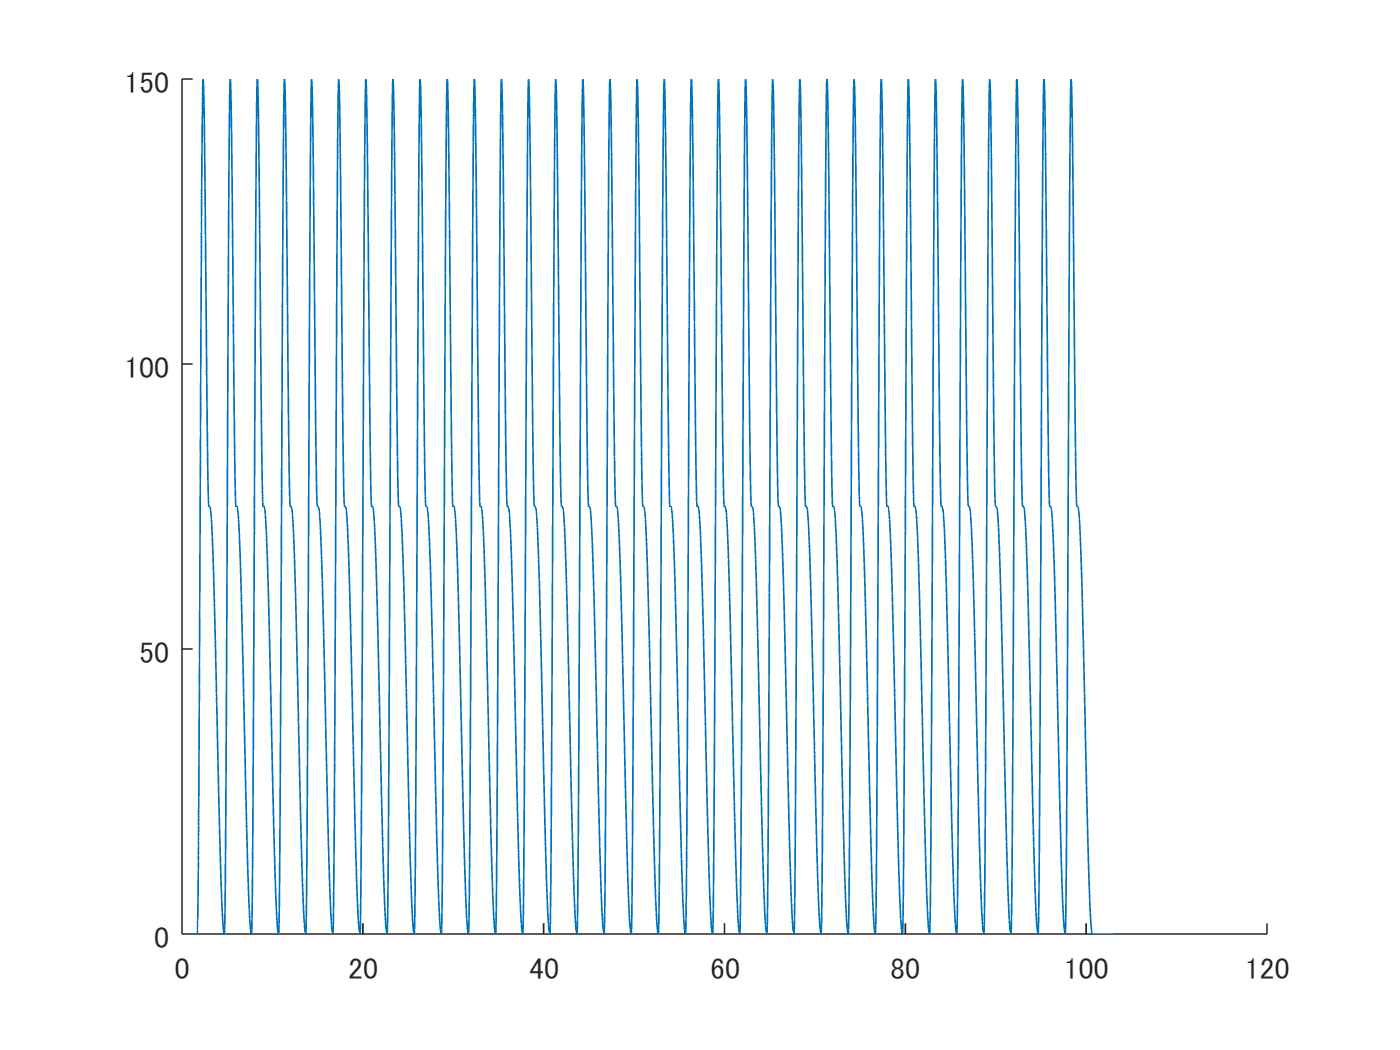

writetable(stockLeftExtend, "stockLeftExtend.csv");
figure;
[stockLeftExtend_x, stockLeftExtend_t] = showGraph(clockTime, deltaTime, absolutePosition);

右ストックの伸縮


L = extendLength; % スライド長 単位 (mm)
startClockTime = stockStartTime; % 開始時刻 (s)
clockTimeU = 0; % 単位 (s)
clockTimeD = period*stockFlyingTimeRate/(stockFlyingTimeRate + stockGroundTimeRate) * upTimeRate/(upTimeRate + downTimeRate); % 単位 (s)
clockTimeSlowD = period*stockFlyingTimeRate/(stockFlyingTimeRate + stockGroundTimeRate) + 0.1; % 単位 (s)
deltaTimeU = period*stockFlyingTimeRate/(stockFlyingTimeRate + stockGroundTimeRate) * upTimeRate/(upTimeRate + downTimeRate); % 単位 (s)
deltaTimeD = period*stockFlyingTimeRate/(stockFlyingTimeRate + stockGroundTimeRate) * downTimeRate/(upTimeRate + downTimeRate); % 単位 (s)
deltaTimeSlowD = period*stockGroundTimeRate/(stockFlyingTimeRate + stockGroundTimeRate) - 0.1; % 単位 (s)
positionU = L; % 単位 (mm)
positionD = L/2; % 単位 (mm)
positionSlowD = 0; % 単位 (mm)

clockTimeUList = (startClockTime + clockTimeU):period:clockTimeLimit; % 単位 (s)
clockTimeDList = (startClockTime + clockTimeD):period:clockTimeLimit; % 単位 (s)
clockTimeSlowDList = (startClockTime + clockTimeSlowD):period:clockTimeLimit; % 単位 (s)
clockTimeUList = clockTimeUList(1:min([length(clockTimeUList), length(clockTimeDList), length(clockTimeSlowDList)]));
clockTimeDList = clockTimeDList(1:min([length(clockTimeUList), length(clockTimeDList), length(clockTimeSlowDList)]));
clockTimeSlowDList = clockTimeSlowDList(1:min([length(clockTimeUList), length(clockTimeDList), length(clockTimeSlowDList)]));
tmp = [clockTimeUList; clockTimeDList; clockTimeSlowDList];
clockTime = tmp(:);
deltaTimeUList = deltaTimeU + 0*clockTimeUList;
deltaTimeDList = deltaTimeD + 0*clockTimeDList;
deltaTimeSlowDList = deltaTimeSlowD + 0*clockTimeSlowDList;
tmp = [deltaTimeUList; deltaTimeDList; deltaTimeSlowDList];
deltaTime = tmp(:);
positionUList = positionU + 0*clockTimeUList;
positionDList = positionD + 0*clockTimeDList;
positionSlowDList = positionSlowD + 0*clockTimeSlowDList;
tmp = [positionUList; positionDList; positionSlowDList];
absolutePosition = tmp(:);
tmp = [zeros(size(clockTimeUList)); ones(size(clockTimeDList)); zeros(size(clockTimeSlowDList));];
useStiffness = tmp(:);

clockTime(end+1) = clockTimeLimit + period/2;
deltaTime(end+1) = period/2;
absolutePosition(end+1) = 0;
useStiffness(end+1) = 0;

stockRightExtend = table(clockTime, deltaTime, absolutePosition, useStiffness)

stockRightExtend = 100×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

     1.6875       0.64286           150                0      
     2.3304       0.64286            75                1      
     3.0732        1.6143             0                0      
     4.6875       0.64286           150                0      
     5.3304       0.64286            75                1      
     6.0732        1.6143             0                0      
     7.6875       0.64286           150                0      
     8.3304       0.64286            75                1      
     9.0732        1.6143             0                0      
     10.688       0.64286           150                0      
      11.33       0.64286            75                1      
     12.073        1.6143             0                0      
     13.688       0.64286           150                0      
      14.33       0.642

writetable(stockRightExtend, "stockRightExtend.csv");
figure;
[stockRightExtend_x, stockRightExtend_t] = showGraph(clockTime, deltaTime, absolutePosition);

左ストックのスライダ

startClockTime = stockStartTime; % 開始時刻 (s)
clockTimeF = 0; % 単位 (s)
clockTimeB = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
deltaTimeF = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
deltaTimeB = period*stockBackwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
positionF = stockSlideForwardLength; % 単位 (mm)
positionB = -stockSlideBackwardLength; % 単位 (mm)

clockTimeFList = (startClockTime + clockTimeF):period:clockTimeLimit; % 単位 (s)
clockTimeBList = (startClockTime + clockTimeB):period:clockTimeLimit; % 単位 (s)
clockTimeFList = clockTimeFList(1:min([length(clockTimeFList), length(clockTimeBList)]));
clockTimeBList = clockTimeBList(1:min([length(clockTimeFList), length(clockTimeBList)]));
tmp = [clockTimeFList; clockTimeBList];
clockTime = tmp(:);
deltaTimeFList = deltaTimeF + 0*clockTimeFList;
deltaTimeBList = deltaTimeB + 0*clockTimeBList;
tmp = [deltaTimeFList; deltaTimeBList];
deltaTime = tmp(:);
positionFList = positionF + 0*clockTimeFList;
positionBList = positionB + 0*clockTimeBList;
tmp = [positionFList; positionBList];
absolutePosition = tmp(:);

clockTime(end+1) = clockTimeLimit + period/2;
deltaTime(end+1) = period/2;
absolutePosition(end+1) = 0;

useStiffness = zeros(size(clockTime));

stockLeftSlider = table(clockTime, deltaTime, absolutePosition, useStiffness)

stockLeftSlider = 67×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

     1.6875       1.2857             100               0      
     2.9732       1.7143            -400               0      
     4.6875       1.2857             100               0      
     5.9732       1.7143            -400               0      
     7.6875       1.2857             100               0      
     8.9732       1.7143            -400               0      
     10.688       1.2857             100               0      
     11.973       1.7143            -400               0      
     13.688       1.2857             100               0      
     14.973       1.7143            -400               0      
     16.688       1.2857             100               0      
     17.973       1.7143            -400               0      
     19.688       1.2857             100               0      
     20.973       1.7143 

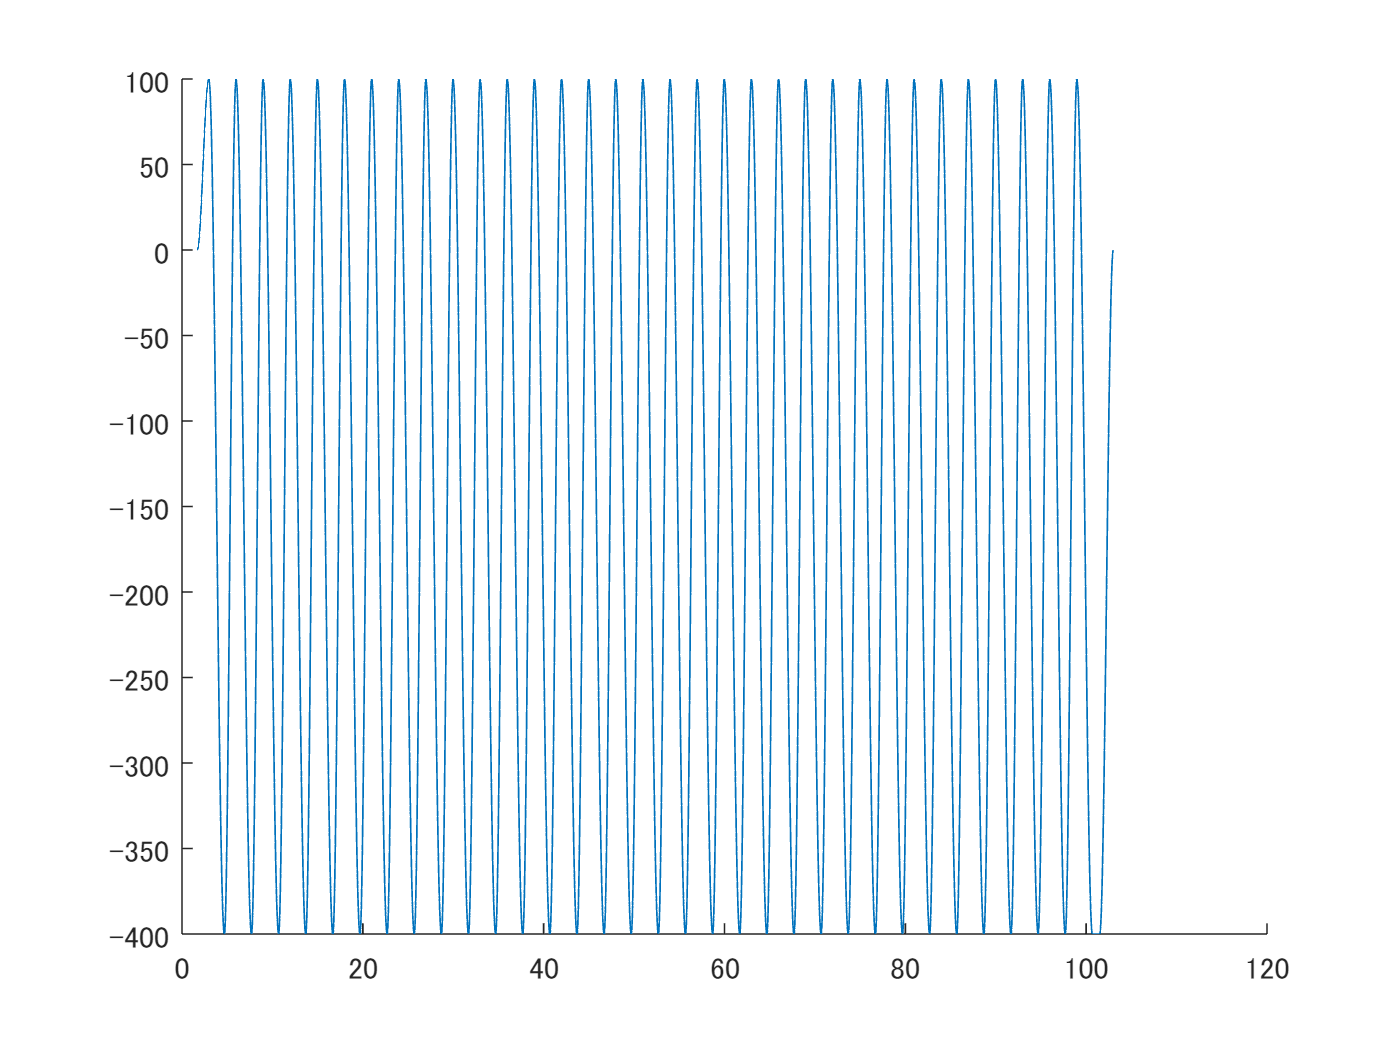

writetable(stockLeftSlider, "stockLeftSlider.csv");
% figure;
% showGraphEveryCmd(clockTime, deltaTime, absolutePosition);
figure;
[stockLeftSlider_x, stockLeftSlider_t] = showGraph(clockTime, deltaTime, absolutePosition);

右ストックのスライダ


L = stockSlideForwardLength; % スライド長 単位 (mm)
startClockTime = stockStartTime; % 開始時刻 (s)
clockTimeF = 0; % 単位 (s)
clockTimeB = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
deltaTimeF = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
deltaTimeB = period*stockBackwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
positionF = stockSlideForwardLength; % 単位 (mm)
positionB = -stockSlideBackwardLength; % 単位 (mm)

clockTimeFList = (startClockTime + clockTimeF):period:clockTimeLimit; % 単位 (s)
clockTimeBList = (startClockTime + clockTimeB):period:clockTimeLimit; % 単位 (s)
clockTimeFList = clockTimeFList(1:min([length(clockTimeFList), length(clockTimeBList)]));
clockTimeBList = clockTimeBList(1:min([length(clockTimeFList), length(clockTimeBList)]));
tmp = [clockTimeFList; clockTimeBList];
clockTime = tmp(:);
deltaTimeFList = deltaTimeF + 0*clockTimeFList;
deltaTimeBList = deltaTimeB + 0*clockTimeBList;
tmp = [deltaTimeFList; deltaTimeBList];
deltaTime = tmp(:);
positionFList = positionF + 0*clockTimeFList;
positionBList = positionB + 0*clockTimeBList;
tmp = [positionFList; positionBList];
absolutePosition = tmp(:);

clockTime(end+1) = clockTimeLimit + period/2;
deltaTime(end+1) = period/2;
absolutePosition(end+1) = 0;

useStiffness = zeros(size(clockTime));

stockRightSlider = table(clockTime, deltaTime, absolutePosition, useStiffness)

stockRightSlider = 67×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

     1.6875       1.2857             100               0      
     2.9732       1.7143            -400               0      
     4.6875       1.2857             100               0      
     5.9732       1.7143            -400               0      
     7.6875       1.2857             100               0      
     8.9732       1.7143            -400               0      
     10.688       1.2857             100               0      
     11.973       1.7143            -400               0      
     13.688       1.2857             100               0      
     14.973       1.7143            -400               0      
     16.688       1.2857             100               0      
     17.973       1.7143            -400               0      
     19.688       1.2857             100               0      
     20.973       1.7143

writetable(stockRightSlider, "stockRightSlider.csv");
% figure;
% showGraphEveryCmd(clockTime, deltaTime, absolutePosition);
figure;
[stockRightSlider_x, stockRightSlider_t] = showGraph(clockTime, deltaTime, absolutePosition);

左ストック 前後傾

LF = tiltForwardDeg; % 単位 (deg)
LB = tiltBackwardDeg; % 単位 (deg)
startClockTimeLeftTilt = stockStartTime  - period*stockBackwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate)*1/4; % 開始時刻 (s)
clockTimeB = 0; % 単位 (s)
clockTimeF = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
leftTiltDeltaTimeB = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
leftTiltDeltaTimeF = period*stockBackwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
% leftTiltDelayTimeB = period*stockBackwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate) - leftTiltDeltaTimeF;
leftTiltDelayTimeB = 0;
leftTiltDelayTimeF = 0;
positionB = LB; % 単位 (deg)
positionF = LF; % 単位 (deg)

clockTimeBList = (startClockTimeLeftTilt + clockTimeB):period:clockTimeLimit; % 単位 (s)
clockTimeFList = (startClockTimeLeftTilt + clockTimeF):period:clockTimeLimit; % 単位 (s)
clockTimeBList = clockTimeBList(1:min([length(clockTimeFList), length(clockTimeBList)]));
clockTimeFList = clockTimeFList(1:min([length(clockTimeFList), length(clockTimeBList)]));
tmp = [clockTimeBList; clockTimeFList];
clockTime = tmp(:);
deltaTimeBList = leftTiltDeltaTimeB + 0*clockTimeBList;
deltaTimeFList = leftTiltDeltaTimeF + 0*clockTimeFList;
tmp = [deltaTimeBList; deltaTimeFList];
deltaTime = tmp(:);
positionBList = positionB + 0*clockTimeBList;
positionFList = positionF + 0*clockTimeFList;
tmp = [positionBList; positionFList];
absolutePosition = tmp(:);

clockTime(end+1) = clockTimeLimit + period/2;
deltaTime(end+1) = period/2;
absolutePosition(end+1) = 0;

useStiffness = zeros(size(clockTime));

leftTilt = table(clockTime, deltaTime, absolutePosition, useStiffness)

leftTilt = 67×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

     1.2589       1.2857              0                0      
     2.5446       1.7143            -20                0      
     4.2589       1.2857              0                0      
     5.5446       1.7143            -20                0      
     7.2589       1.2857              0                0      
     8.5446       1.7143            -20                0      
     10.259       1.2857              0                0      
     11.545       1.7143            -20                0      
     13.259       1.2857              0                0      
     14.545       1.7143            -20                0      
     16.259       1.2857              0                0      
     17.545       1.7143            -20                0      
     19.259       1.2857              0                0      
     20.545       1.7143        

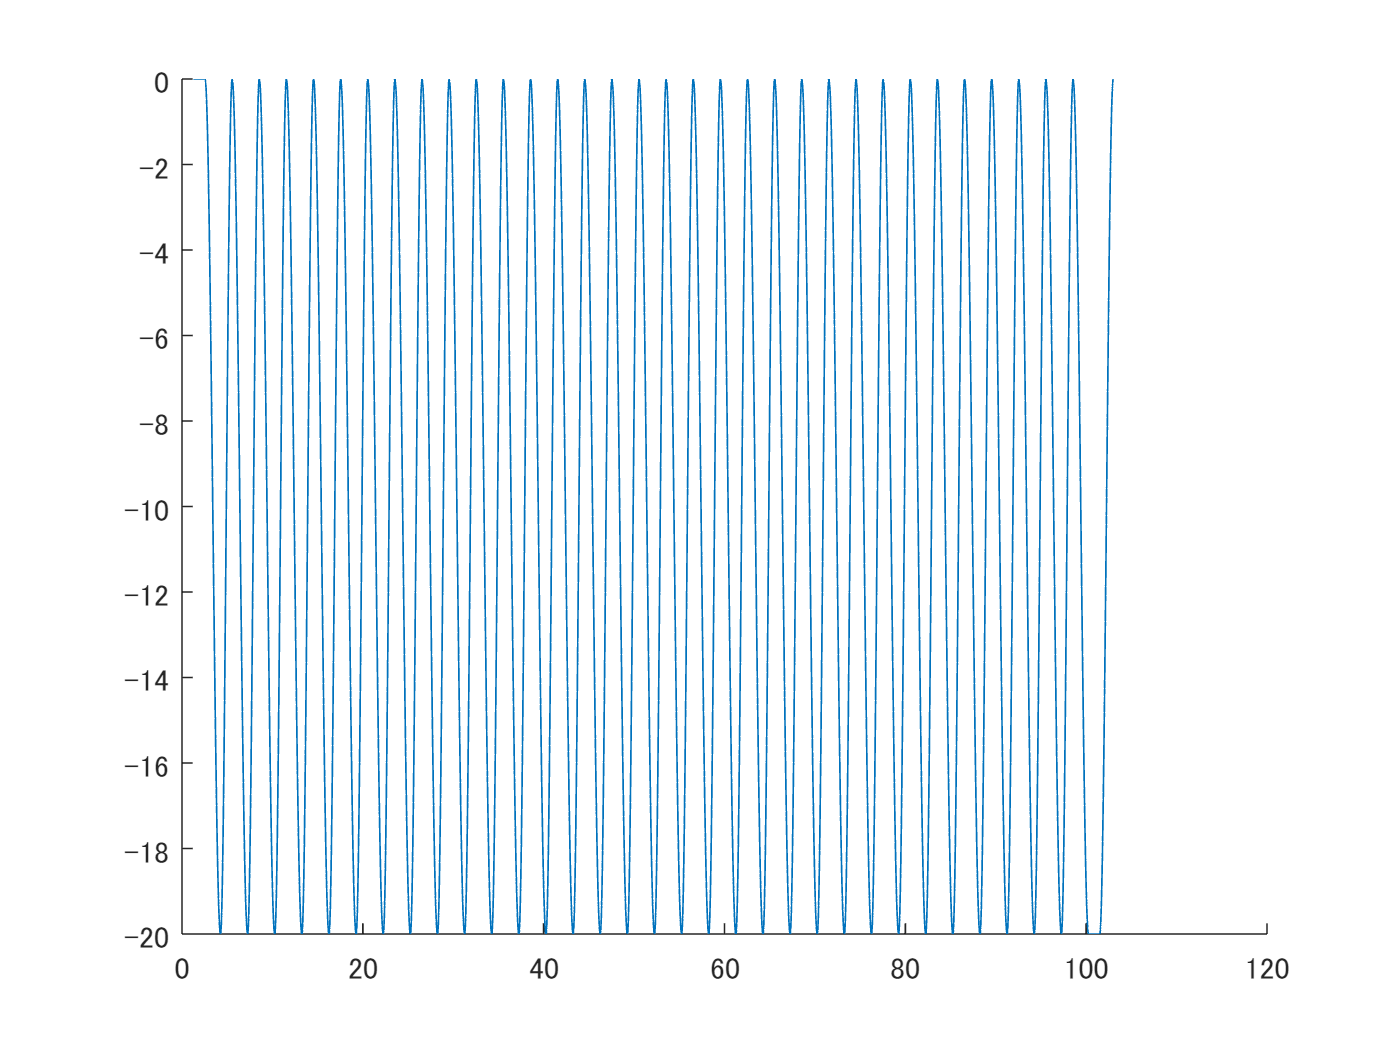

writetable(leftTilt, "leftTilt.csv");
% figure;
% showGraphEveryCmd(clockTime, deltaTime, absolutePosition);
figure;
[leftTilt_x, leftTilt_t] = showGraph(clockTime, deltaTime, absolutePosition);

右ストック 前後傾

LF = tiltForwardDeg; % 単位 (deg)
LB = tiltBackwardDeg; % 単位 (deg)
startClockTimeRightTilt = stockStartTime - period*stockBackwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate)*1/4; % 開始時刻 (s)
clockTimeB = 0; % 単位 (s)
clockTimeF = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
rightTiltDeltaTimeB = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
rightTiltDeltaTimeF = period*stockBackwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
% rightTiltDelayTimeB = period*stockBackwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate) - rightTiltDeltaTimeF;
rightTiltDelayTimeB = 0;
rightTiltDelayTimeF = 0;
positionB = LB; % 単位 (deg)
positionF = LF; % 単位 (deg)

clockTimeBList = (startClockTimeRightTilt + clockTimeB):period:clockTimeLimit; % 単位 (s)
clockTimeFList = (startClockTimeRightTilt + clockTimeF):period:clockTimeLimit; % 単位 (s)
clockTimeBList = clockTimeBList(1:min([length(clockTimeFList), length(clockTimeBList)]));
clockTimeFList = clockTimeFList(1:min([length(clockTimeFList), length(clockTimeBList)]));
tmp = [clockTimeBList; clockTimeFList];
clockTime = tmp(:);
deltaTimeBList = rightTiltDeltaTimeB + 0*clockTimeBList;
deltaTimeFList = rightTiltDeltaTimeF + 0*clockTimeFList;
tmp = [deltaTimeBList; deltaTimeFList];
deltaTime = tmp(:);
positionBList = positionB + 0*clockTimeBList;
positionFList = positionF + 0*clockTimeFList;
tmp = [positionBList; positionFList];
absolutePosition = tmp(:);

clockTime(end+1) = clockTimeLimit + period/2;
deltaTime(end+1) = period/2;
absolutePosition(end+1) = 0;

useStiffness = zeros(size(clockTime));

rightTilt = table(clockTime, deltaTime, absolutePosition, useStiffness)

rightTilt = 67×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

     1.2589       1.2857              0                0      
     2.5446       1.7143            -20                0      
     4.2589       1.2857              0                0      
     5.5446       1.7143            -20                0      
     7.2589       1.2857              0                0      
     8.5446       1.7143            -20                0      
     10.259       1.2857              0                0      
     11.545       1.7143            -20                0      
     13.259       1.2857              0                0      
     14.545       1.7143            -20                0      
     16.259       1.2857              0                0      
     17.545       1.7143            -20                0      
     19.259       1.2857              0                0      
     20.545       1.7143       

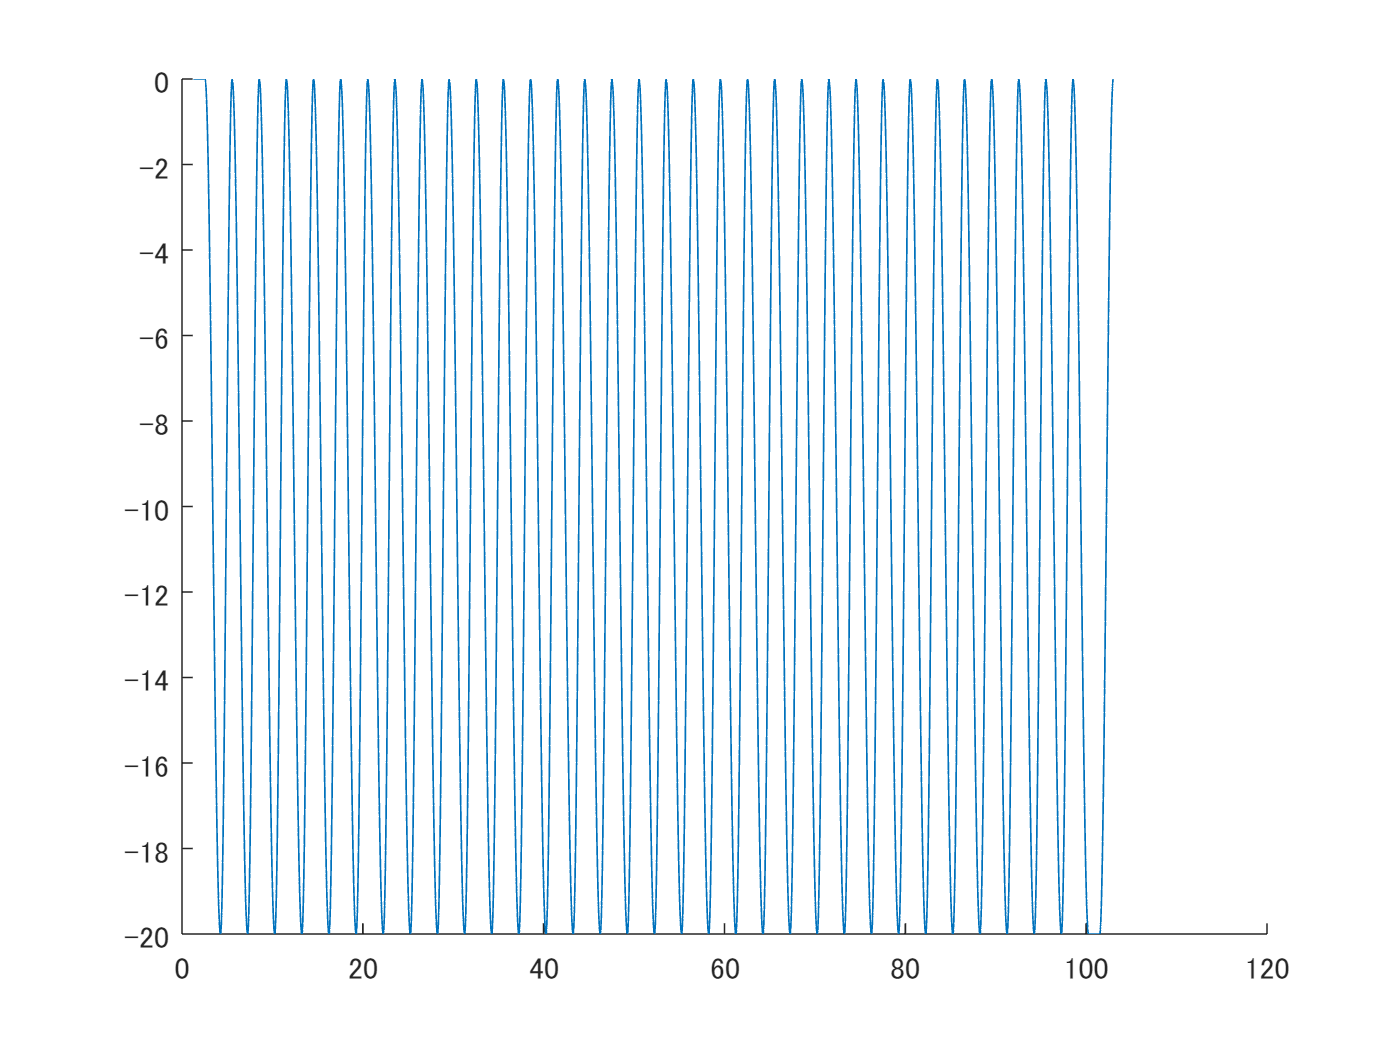

writetable(rightTilt, "rightTilt.csv");
% figure;
% showGraphEveryCmd(clockTime, deltaTime, absolutePosition);
figure;
[rightTilt_x, rightTilt_t] = showGraph(clockTime, deltaTime, absolutePosition);

TiltCSV = table( ...
    period, tiltBackwardDeg, tiltForwardDeg, tiltBackwardTimeRate, tiltForwardTimeRate, startClockTimeLeftTilt, startClockTimeRightTilt, ...
    leftTiltDeltaTimeB, leftTiltDeltaTimeF, rightTiltDeltaTimeB, rightTiltDeltaTimeF, ...
    leftTiltDelayTimeB, leftTiltDelayTimeF, rightTiltDelayTimeB, rightTiltDelayTimeF ...
    )

TiltCSV = 1×15 table
    period    tiltBackwardDeg    tiltForwardDeg    tiltBackwardTimeRate    tiltForwardTimeRate    startClockTimeLeftTilt    startClockTimeRightTilt    leftTiltDeltaTimeB    leftTiltDeltaTimeF    rightTiltDeltaTimeB    rightTiltDeltaTimeF    leftTiltDelayTimeB    leftTiltDelayTimeF    rightTiltDelayTimeB    rightTiltDelayTimeF
    ______    _______________    ______________    ____________________    ___________________    ______________________    _______________________    __________________    __________________    ___________________    ___________________    __________________    __________________    ___________________    ___________________

      3              0                -20                   3                       4                     1.2589                    1.2589                   1.2857                1.7143                1.2857                 1.7143                   0                     0                      0                      0    

writetable(TiltCSV, 'tilt.csv');

signal_lifter = timeseries(lifter_x, lifter_t, Name='lifter');
signal_leftPedal = timeseries(leftPedal_x, leftPedal_t, Name='leftPedal');
signal_rightPedal = timeseries(rightPedal_x, rightPedal_t, Name='rightPedal');
signal_seatLeftSlider = timeseries(seatLeftSlider_x, seatLeftSlider_t, Name='seatLeftSlider');
signal_seatRightSlider = timeseries(seatRightSlider_x, seatRightSlider_t, Name='seatRightSlider');
signal_stockLeftSlider = timeseries(stockLeftSlider_x, stockLeftSlider_t, Name='stockLeftSlider');
signal_stockRightSlider = timeseries(stockRightSlider_x, stockRightSlider_t, Name='stockRightSlider');
signal_stockLeftExtend = timeseries(stockLeftExtend_x, stockLeftExtend_t, Name='stockLeftExtend');
signal_stockRightExtend = timeseries(stockRightExtend_x, stockRightExtend_t, Name='stockRightExtend');
signal_leftTilt = timeseries(leftTilt_x, leftTilt_t, Name="leftTilt");
signal_rightTilt = timeseries(rightTilt_x, rightTilt_t, Name="rightTilt");

Scenario = Simulink.SimulationData.Dataset;

Scenario{1} = signal_lifter;
Scenario{2} = signal_leftPedal;
Scenario{3} = signal_rightPedal;
Scenario{4} = signal_seatLeftSlider;
Scenario{5} = signal_seatRightSlider;
Scenario{6} = signal_stockLeftExtend;
Scenario{7} = signal_stockRightExtend;
Scenario{8} = signal_stockLeftSlider;
Scenario{9} = signal_stockRightSlider;
Scenario{10} = signal_leftTilt;
Scenario{11} = signal_rightTilt;


% Scenario{2} = SignalStickRightPitch;
% Scenario{2}.Name = 'SignalStickRightPitch';
% Scenario{5} = signal_stockLeftPitch;
% Scenario{5}.Name = 'SignalStickLeftPitch';

save('../../../scenario.mat', 'Scenario');

sim("Simulink.slx");

clear;

function showGraphEveryCmd(clockTime, deltaTime, absolutePosition)
    t = 0:0.001:deltaTime(1);
    x = absolutePosition(1)*(1 + cos(pi*t/deltaTime(1) + pi))/2;
    plot(t + clockTime(1), x);
    hold on;
    for idx = 2:length(clockTime)
        t = 0:0.01:deltaTime(idx);
        x = (absolutePosition(idx) - absolutePosition(idx-1)) * (1 + cos(pi*t/deltaTime(idx) + pi))/2 + absolutePosition(idx - 1);
        plot(t + clockTime(idx), x);
    end
end

function [ret_x, ret_t] = showGraph(clockTime, deltaTime, absolutePosition)
    % ret_t = [];
    t = (0:0.001:deltaTime(1))';
    x = absolutePosition(1)*(1 + cos(pi*t/deltaTime(1) + pi))/2;
    % plot(t + clockTime(1), x);
    ret_x = x;
    ret_t = t + clockTime(1);
    hold on;
    for idx = 2:length(clockTime)
        t = (0:0.01:deltaTime(idx))';
        x = (absolutePosition(idx) - absolutePosition(idx-1)) * (1 + cos(pi*t/deltaTime(idx) + pi))/2 + absolutePosition(idx - 1);
        % plot(t + clockTime(idx), x);
        ret_t = [ret_t; t + clockTime(idx)];
        ret_x = [ret_x; x];
    end
    plot(ret_t, ret_x);
end